6.  Find the finite-difference solution of the heat-conduction problem

PDE                    $u_{\textrm{tt}} =u_{\textrm{xx}}$                    $0<x<1$,    $t>0$

BCs                     $\left\lbrace \begin{array}{cc}
u\left(0,t\right)=0 & t>0\\
u\left(1,t\right)=0 & t>0
\end{array}\right.$

IC                        $u\left(x,0\right)=\sin \left(\pi x\right)$   $0\le x\le 1$ 

for t=0.005, 0.010, 0.015 by the explicit method. Let $h=\delta x=0\ldotp 1$. Plot the solution at x=0, 0.1, 0.2, 0.3, ..., 0.9, 1 for t=0.015.

Solving the problem according to the following step

step 1: Input H=0.1,K=0.005 and end point of t,

step 2: calculate number of grid point on x-direction N and t-direction M.

            N=1/H+1;

            M=1/K+1;

step 3: compute the ratio $R=\frac{K}{H^2 }$

step 4: for i=1:M-1

                for j=2:N-1

                    compute u(i + 1, j) = u(i, j) + R*[u(i, j + 1) - 2*u(i, j) + u(1, j - 1)]

                end

            u(i + 1, N) = [u(i + 1, N - 1) + HG(i + 1)]/(H + 1)

            since in this problem the boundary on the left and right side is 0

            u(i + 1, N) = 0

            end

clear
%step 1 input H, K and ending point p
H = 0.1;
K = 0.005;
p = 0.015;

%step 2, calculate N, M
N = 1/H + 1;
M = p/K + 1;

%step 3, calculate R
R = K/(H*H);

x = linspace(0, 1, N);%generate x = 0, 0.1, 0.2, ... ,0.9, 1
y = linspace(K, p, M);%generate t = 0.005, 0.010, 0.015

%initial condition 
u = zeros(M, N);%initial the matrix
u(1, :) = sin(pi*x);%set initial condition u(x, 0) = sin(pi*x)

%step 4
for i = 1:M - 1
    %loop for i:M-1
    for j = 2:N - 1
        %loop for j=2:N-1
        u(i + 1, j) = u(i, j) + R*(u(i, j + 1) - 2*u(i, j) + u(i, j - 1)); 
    end
    u(i + 1, N) = 0;
end

u = flipud(u);%since the matrix is upside down with the problem we need to flip it up down
result_t_015 = u(1, :)%the result of PDE with t=0.015;

result_t_015 =          0    0.2658    0.5056    0.6959    0.8181    0.8602    0.8181    0.6959    0.5056    0.2658         0


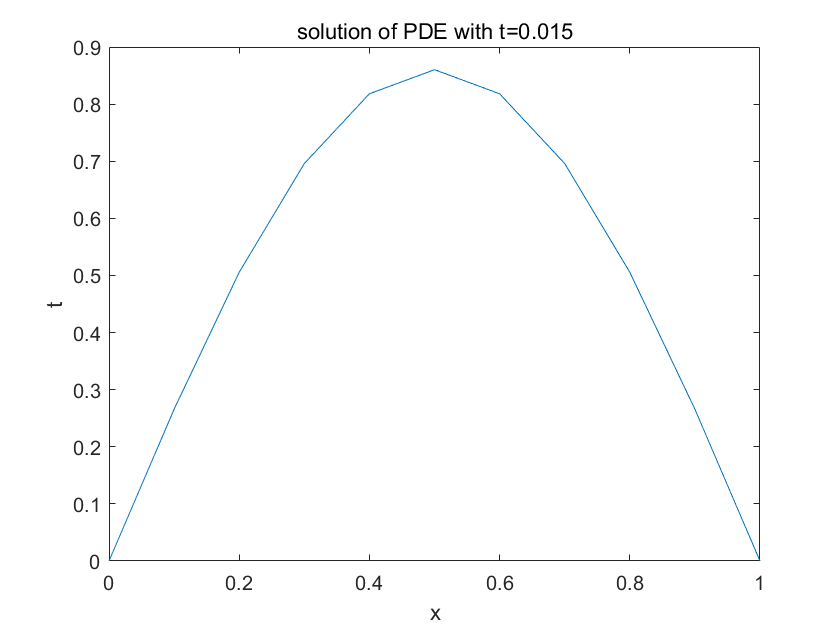

plot(x, u(1, :))%only plot the row fot t = 0.015
title('solution of PDE with t=0.015')
xlabel('x')
ylabel('t')